3.5    （三次样条）实时脚本

由张志涌编写、修改于 2023.1。

(1)绘图3.6

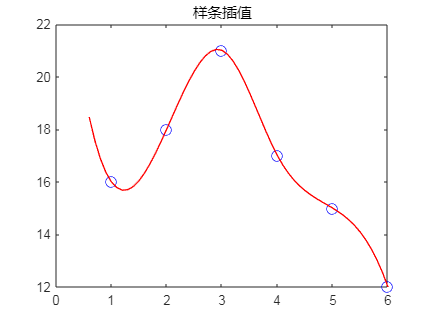

x = 1:6;
y = [16 18 21 17 15 12];
xq=0.6:0.1:6;
p = spline(x,y,xq);
h=plot(x,y,'ob',xq,p,'-r');
h(1).MarkerSize=8;
h(2).LineWidth=1;
title('样条插值')

(2)绘图3.7

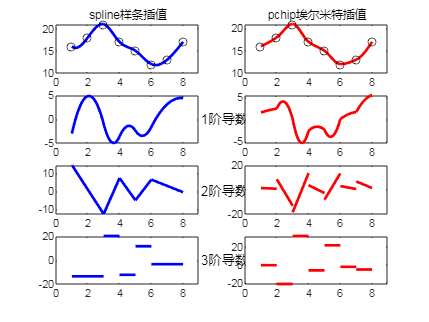

xx = 1:8;
yy = [16 18 21 17 15 12 13 17];
SC{1,1}=spline(xx,yy);
SC{1,2}=pchip(xx,yy);
SC{4,2}=[];
for ii=1:3
    SC{ii+1,1}=fnder(SC{1,1},ii);
    SC{ii+1,2}=fnder(SC{1,2},ii);
end
clf
for ii=1:4
    subplot(4,2,2*ii-1)
    fnplt(SC{ii,1},'b-','j')
    if ii>1
        text(9.1,0,[int2str(ii-1),'阶导数'])
    end
    xlim([0,9])
    subplot(4,2,2*ii)
    fnplt(SC{ii,2},'r-','j')
    xlim([0,9])
end
subplot(4,2,1)
line(xx,yy,'Color','k','Marker','o','LineStyle','none')
title('spline样条插值')
subplot(4,2,2)
line(xx,yy,'Color','k','Marker','o','LineStyle','none')
title('pchip埃尔米特插值')